# Two-player quantum game visualization

Consider quantum prisoners' dilemma:

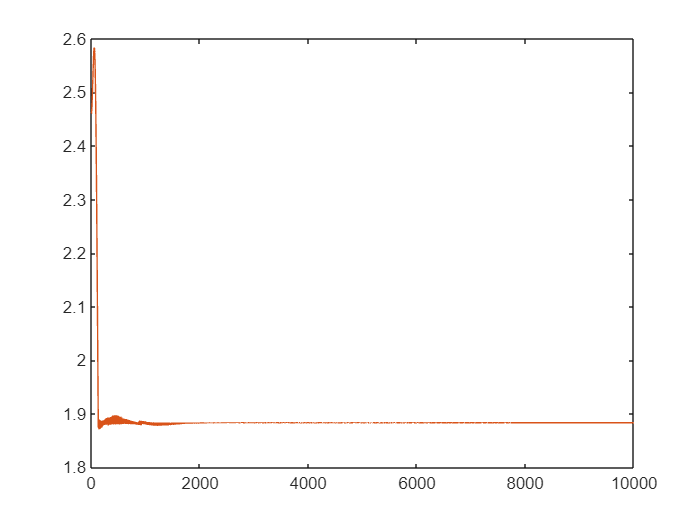

% Payoff matrix for prisoner's dilemma
H1 = diag([3,0,5,1]);
H2 = diag([3,5,0,1]);

% preparing for initial states
lam = 0.27; % Schmidt eigenvalues, characterizing entanglement
InitialState = @(lam) sqrt(lam) * [0;0;0;1] + sqrt(1-lam) * [1;0;0;0];

% lam=0: starting from cooperation
% lam=1: starting from mutual defect

% other parameters
N = 2; % number of players
niter = 10000; % number of iterations
eps = 1e-2* exp(-linspace(0,12,niter)); % stepsize for strategy updates

% Information for game
GamePayoff = {H1, H2};
GameState = zeros(4, niter); % underlying state in the protoco lat each step
GamePayoffData = zeros(2, niter);
% the update on strategy for players at each round
GameStrategy = {zeros(2, 2, niter), zeros(2, 2, niter)};

% initialize
GameStrategy{1}(:,:,1) = eye(2);
GameStrategy{2}(:,:,1) = eye(2);
GameState(:,1) = InitialState(lam);
GamePayoffData(1,1) = GameState(:,1)'*GamePayoff{1}*GameState(:,1);
GamePayoffData(2,1) = GameState(:,1)'*GamePayoff{2}*GameState(:,1);

for iter = 2:niter
    for i = 1:N
        game_state = GameState(:,iter-1);
        [n,sigma_dir] = vphi(GamePayoff,game_state,N,i);
        GameStrategy{i}(:,:,iter) = expm(1i*eps(iter)*sigma_dir) * GameStrategy{i}(:,:,iter-1);
    end

    GameState(:,iter) = kron(GameStrategy{1}(:,:,iter),GameStrategy{2}(:,:,iter)) * GameState(:,1);
    for i = 1:N
        GamePayoffData(i,iter) = GameState(:,iter)'*GamePayoff{i}*GameState(:,iter);
    end
end
figure()
plot(0:niter-1,real(GamePayoffData))

Visualization of strategies taken

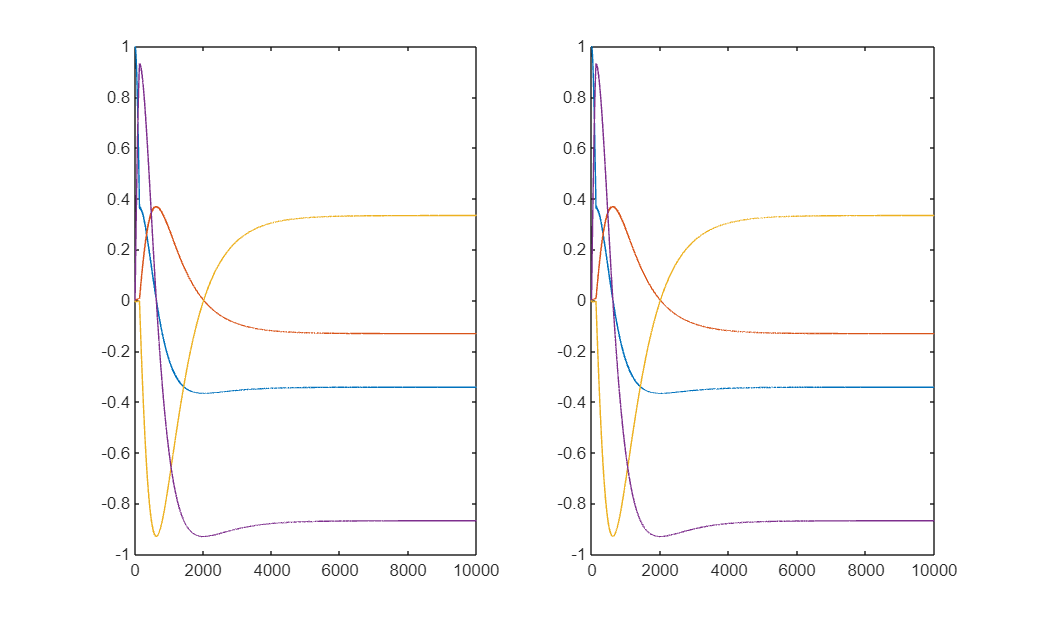

% extracting the four components of SU(2) matrices
GameStrategy_S3 = {zeros(4, niter), zeros(4, niter)};
for i = 1:2
    for iter = 1:niter
        X = real(GameStrategy{i}(1,1,iter));
        Y = imag(GameStrategy{i}(1,1,iter));
        Z = real(GameStrategy{i}(1,2,iter));
        U = imag(GameStrategy{i}(1,2,iter));

        GameStrategy_S3{i}(:,iter) = [X;Y;Z;U];
    end
end
figure(Position=[400,1000,2000,1200])
subplot(1,2,1)
plot(0:niter-1,GameStrategy_S3{1});
subplot(1,2,2)
plot(0:niter-1,GameStrategy_S3{2});

% On a 3-sphere, use stereographic projection onto R3

function [n,sigma_dir] = vphi(GamePayoff,game_state,N,i)
% try first order, i.e. commutator
h = GamePayoff{i};
n = zeros(3,1);
PayInc = zeros(1,3);
for a = 1:3
    PayInc(a) = game_state'*1i*(h*PauliI(N,i,a)-PauliI(N,i,a)*h)*game_state;
end

% did not take into degenerate cases
[MaxPayInc,MaxPayIncIndex] = max(PayInc);
if MaxPayInc > 1e-10
    n(MaxPayIncIndex) = 1;
else
    % Nash stationary state. To update the strategies, need to go one order
    % higher
    PayInc = zeros(3); % now a hermitian matrix
    for a = 1:3
        for b = 1:3
            PayInc(a,b) = game_state'*(1/2*(PauliI(N,i,a)*h*PauliI(N,i,b)+PauliI(N,i,b)*h*PauliI(N,i,a))-eye(2^N))*game_state;
        end
    end
    % Likewise to the gradient descent method
    [spec,l] = eig(PayInc,'vector');
    [MaxEigval,MaxEigvalIndex] = max(l);
    if MaxEigval > 1e-10
        n = spec(:,MaxEigvalIndex);
    end
end
sigma_dir = n(1) * [0,1;1,0] + n(2) * [0,-1i;1i,0] + n(3) * [1,0;0,-1];

end